# Design of Finned Tube Heat Exchanger

#### *E349 - Air Cooled Heat Exchanger*

Group 12: Aswin Raghunathan (5128188) & Shyam Sundar Hemamalini (5071984)

clear variables;

## 1.1. Estimation of Heat Flux

We are given the following specifications.

m_water = 100; % kg/s
T_in_water = 39 + 273.15; % K
T_out_water = 34 + 273.15; % K

The enthalpy of water at the given temperatures have been determined to be as below.

h_in_water = 163.35*1000; % J/kg
h_out_water = 142.45*1000; % J/kg

Now, the duty can be determined as:

Q_dot = m_water*(h_in_water - h_out_water) % W

Q_dot = 2090000

## 1.2. Determination of Outlet Air Temperature

The following specifications are also provided.

m_air = 140; % kg/s
T_in_air = 20 + 273.15; % K

The enthalpy of air at the inlet has been determined from the inlet temperature to be as below.

h_in_air = 419.4*1000; % J/kg

A simple substitution in the energy balance will give us the outlet enthalpy of air as:

h_out_air = h_in_air + (m_water*(h_in_water - h_out_water))/m_air % J/kg

h_out_air = 4.3433e+05

The outlet temperature of air is then determined from REFPROP as below.

T_out_air = 34.85 + 273.15 % K

T_out_air = 308

## 2. Determination of Physical Properties

The physical properties of both water and air are evaluated at the mean temperatures which are determined as:

T_mean_air = T_in_air/2 + T_out_air/2 % K

T_mean_air = 300.5750

T_mean_water = (T_in_water + T_out_water)/2 % K

T_mean_water = 309.6500


rho_water = 993.47; % kg/m^3
rho_air = 1.1747; % kg/m^3

visc_water = 6.9809e-4; % Pa s
visc_air = 1.8565e-5; % Pa s

k_water = 0.62553; % W/mK
k_air = 0.026427; % W/mK

Cp_water = 4179.5; % J/kg
Cp_air = 1.0064e3; % J/kg

## 3. Estimation of Tube Side Heat Transfer Coefficient

The following design parameters are defined:

d_out = 25.4e-3; % m
t = 1.5e-3; % m
d_in = d_out- 2*t; % m

The velocity in the tube side is initially assumed as 1.5 m/s and the flow properties are determined.

v_tube = 1.5; % m/s
Re_tube = rho_water*v_tube*d_in/visc_water

Re_tube = 4.7817e+04

Pr_tube = Cp_water*visc_water/k_water

Pr_tube = 4.6643

From the above, the heat transfer coefficient in the tube side can be determined from the given correlations as below.

Nu = 0.023*(Re_tube^0.8)*(Pr_tube^0.33);
h_i = Nu*k_water/d_in % W/m^2K

h_i = 5.9169e+03

## 4. Assumption of Internal Fouling Coefficient

As the fluid in the tube side is water, it is recommended to take a moderate fouling coefficient.

h_id = 3000; % W/m^2K

## 5. Estimation of Air side Heat Transfer Coefficient

The air side heat transfer coefficient depends on the properties of the fins used. Initially, we assume an efficiency and an area ratio as below.

eff_fin = 0.9;
A_ratio = 1/20;

Using an approximate value for the flow velocity, we can determine an estimate for the air side heat transfer coefficient as below.

v_air = 2.5; % m/s
Re_air = rho_air*v_air*d_out/visc_air

Re_air = 4.0180e+03

Pr_air = Cp_air*visc_air/k_air

Pr_air = 0.7070

Nu_a = 0.28*(Re_air^0.6)*Pr_air^(0.33)

Nu_a = 36.2969

In the above, the mean temperature of air has been used to determine the flow properties.

h_f = Nu_a*k_air/d_out % W/m^2K

h_f = 37.7645

## 6. Assumption of External Fouling Coefficient

As recommended by Sinnott and Towler, an external fouling coefficient for air has been assumed as 5000 W/m2K.

h_df = 5000; % W/m^2K

## 7. Calculation of Overall Heat Transfer Coefficient

The material of the tubing is assumed to be stainless steel as it is generally non-corrosive than low carbon steel or aluminium and is considerably cheap.

k_metal = 17; % W/mK

Now, the overall heat transfer coefficient can be estimated from the assumed properties.

term = (1/h_f + 1/h_df)*A_ratio/eff_fin + d_out*log(d_out/d_in)/(2*k_metal) +...
    d_out/(d_in*h_i) + d_out/(d_in*h_id); 
U_1 = 1/term % W/m^2K

U_1 = 466.0413

## 8. Estimation of Ambient Air Temperature

As the inlet air temperature in given as 20°C, the ambient air temperature determination is not necessary.

## 9. Determination of Mean Temperature Difference

Now, we have the formula for logarithmic mean temperature difference as:

T_lmtd = ((T_in_water-T_out_air)-(T_out_water-T_in_air))...
    /log((T_in_water - T_out_air)/(T_out_water - T_in_air)) % K

T_lmtd = 8.1007

As the heat transfer occurs in the form of a cross flow, a correction factor is needed. The value for the factor has been determined from the tables as below. Hence, we find the mean temperature difference as follows.

F_t = 0.9;
T_m = T_lmtd*F_t % K

T_m = 7.2906

## 10. Estimation of Bare Tube Area

From the estimated values, we can determine the area of tubing required for the given duty.

A = Q_dot/(U_1*T_m) % m^2

A = 615.1181

## 11. Estimation of Number of Tubes

The determined area has to be divided properly into tubing. The following design choices are made.

d_out = 25.4e-3; % m
t_tube = 1.5e-3; % m
d_in = d_out- 2*t; % m
L_tube = 12; % m

The design choices for the fin are also made, viz., the fin height, the fin pitch, the fin thickness and the overall diameter.

h_fin = 15e-3; % m
pitch_fin = 2.8e-3; % m
delta_fin = 0.45e-3; % m
D_OUT = d_out + 2*h_fin; % m

The area of a single tube is calculated and hence, a rough estimate of the number of tubes is obtained as below.

A_tube = pi*d_out*L_tube % m^2

A_tube = 0.9576

N_tubes = round(A/A_tube)

N_tubes = 642

Initially, the number of heat exchangers is assumed to be 1 for cost concerns.

N_hex = 1

N_hex = 1

N_tubes_hex = round(N_tubes/N_hex)

N_tubes_hex = 642

## 12. Choice of Tube Layout and Arrangement

A multipass staggered tube arrangement is chosen. As the mass flow rate for the tube side is quite high, a high number of tube rows is chosen.

N_rows = 8

N_rows = 8

N_tubes_row = round(N_tubes_hex/N_rows)

N_tubes_row = 80

The tube spacing is chosen based on industrial standards. Hence, the estimate for the width of the heat exchanger can be determined.

s_tube = 0.0635; % m
B = s_tube*(N_tubes_row+1) % m

B = 5.1435

It can be seen that the width marginally exceeds 5m. This margin is accepted for now. The velocity of the flow in the tube side is then determined by assuming 4 passes. 

N_p = 4

N_p = 4

A_i = pi*(d_in^2)/4; % m^2
u_tube = (m_water/N_hex)*N_p/(N_rows*N_tubes_row)/A_i/rho_water % m/s

u_tube = 1.5964

## 13. Determination of Bundle Area

The total air flow area can be estimated now that all the design parameters are known.

A_bundle = s_tube*(N_tubes_row+1)*L_tube % m^2

A_bundle = 61.7220

## 14. Estimation of Air side Flow Rate

An air side velocity of 2.5m/s is assumed and the total air side flow rate is determined. 

v_air = 2.5; % m/s
Q_air = v_air*A_bundle % m^3/s

Q_air = 154.3050

## 15.1. Estimation of Pressure Drop

As the temperature of the fluid in the tube side varies, a viscosity correction factor is required. The tube wall temperature has been estimated from the following relation.

T_wall_tube = T_mean_water + U_1*(T_mean_air - T_mean_water)/h_i % K

T_wall_tube = 308.9352

visc_water_w = 7.0680e-4; % Pa s

The friction factor has been estimated from the table given.

jf = 3.2e-3; % friction factor
m = 0.14; % turbulent flow

Now, the pressure drop in the tube side can be estimated as below.

P_tube = N_p * (8*jf*(L_tube/d_in)*((visc_water/visc_water_w)^(-m)) + 2.5) ...
    * rho_water * u_tube^2 /2 % Pa

P_tube = 8.2224e+04

It can be seen that the pressure drop is considerably high. Hence, the design choices have to be optimized.

## 15.2 Estimation Fan Power Consumption

The efficiency of the fan and the motor have been assumed. The pressure in the air side is initially assumed to be 150 Pa.

eff_fan = 0.5; 
eff_motor = 0.95;
N_fans = 2;
P_air = 150;

Now, the power required to deliver the air flow rate is then determined. 

W_fan = Q_air*P_air/(eff_fan*eff_motor)/N_fans

W_fan = 2.4364e+04

W_total = W_fan*N_fans*N_hex

W_total = 4.8728e+04

The length of the heat exchanger is not an exact multiple of the width of the heat exchanger. This results in some spacing between the fans. This spacing is uniformly distributed along the length and is determined as follows.

s_fan = (L_tube - N_fans*B)/(N_fans+1)

s_fan = 0.5710

## 16. Optimization of Design Choices

The width of the heat exchanger and the pressure drop are outside the permissible limits of design. Hence, a random search optimization has been performed with three independent parameters: number of heat exchangers, number of tube rows and number of passes. 

c = 1;

for i=1:1000
    
    N_hex = 1 + round(4*rand(1)); % N_hex = {1,2,3,4,5}
    N_rows = 2 + 2*round(4*rand(1)); % N_rows = {2,4,6,8,10}
    N_p = 1 + round(3*rand(1)); % N_pass = {1,2,3,4}

    if mod(N_rows,N_p) == 0 % N_pass must divide N_rows
    N_tubes = round(A/A_tube);
    N_tubes_hex = round(N_tubes/N_hex);
    N_tubes_row = round(N_tubes_hex/N_rows);

    B = s_tube*(N_tubes_row+1); % Width
    
    u = (m_water/N_hex)*N_p/(N_rows*N_tubes_row)...
        /A_i/rho_water; % Velocity
    
    P_tube = N_p * (8*jf*(L_tube/d_in)*...
        ((visc_water/visc_water_w)^(-m)) + 2.5)*...
        rho_water* (u^2) /2; % Pressure

The pressure must be below 0.4 bar to be acceptable. Also, an additional constraint of the width being smaller than 6m is imposed to further reduce the number of possible options.

    if P_tube < 4e4 && B<6

    X(c) = N_rows;
    Y(c) = N_hex;
    Z(c) = N_p;
    

Now, we have three optimization variables corresponding to the design parameters. They are superimposed into a unified optimization variable and scaled such that the higher the 'score' obtained, the better the combination of the design variables are.

    V1 = abs(B-5)/5;
    V2 = abs(u - 1.5)^2/1.5;
    V3 = abs(P_tube - 3e4)/3e4;
    V4 = V1*V2*V3;
    V(c) = 5/(V4);
    c = c+1;
    end
    
    end
end

The qualified values are then plotted in 3D with the optimization variable denoted by the size of the marker and its color.

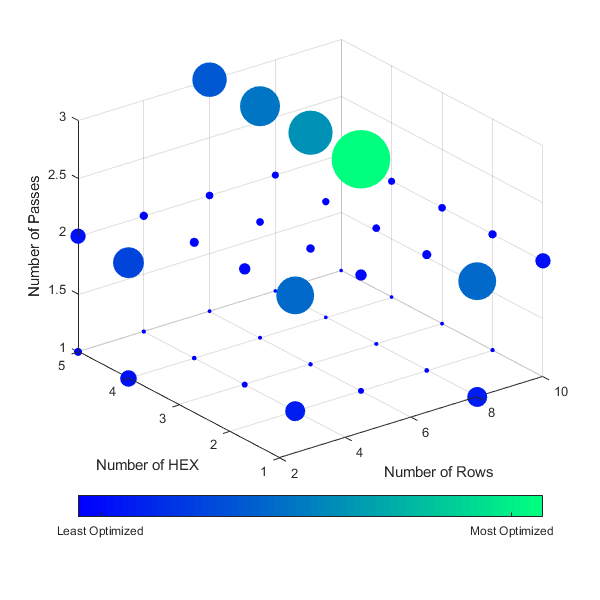

scatter3(X,Y,Z,V,V, 'filled');
set(gcf,'Position',[100 100 600 600])
xlabel('Number of Rows');
ylabel('Number of HEX');
zlabel('Number of Passes');
colormap winter;
colorbar('southoutside','Ticks',[100,1800],...
         'TickLabels',{'Least Optimized','Most Optimized'})
grid on;

It can be seen that one set of values is relatively better than the others. Hence, that is chosen as the optimized design. In order to determine the design values pertaining to the most optimized value, the maximum value is determined and the indices are mapped.

[max,index] = max(V);
N_rows = X(index)

N_rows = 6

N_hex = Y(index)

N_hex = 2

N_p = Z(index)

N_p = 3

### Recalculation of velocity and pressure

The width of the heat exchanger, the velocity of flow in the tube side and the pressure drop in the tube side are then redetermined for the optimized design.

N_tubes_hex = round(N_tubes/N_hex)

N_tubes_hex = 321

N_tubes_row = round(N_tubes_hex/N_rows)

N_tubes_row = 54


B = s_tube*(N_tubes_row+1) % m

B = 3.4925

H = s_tube*(N_rows + 1) % m

H = 0.4445

u_tube = (m_water/N_hex)*N_p/(N_rows*N_tubes_row)/A_i/rho_water

u_tube = 1.1825

P_tube = N_p * (8*jf*(L_tube/d_in)*((visc_water/visc_water_w)^(-m)) + 2.5) ...
    * rho_water * u_tube^2 /2 % Pa

P_tube = 3.3837e+04

It can be seen that all the three parameters are well within the extreme limits and the design is indeed optimized. 

## 13*. Determination of Bundle Area

The bundle area is recalculated.

s_tube = 0.0635; % m
A_bundle = s_tube*(N_tubes_row+1)*L_tube % m^2

A_bundle = 41.9100

## 14*. Estimation of Air side Flow Rate

The air side flow rate is re-estimated.

v_air = 2.5; % m/s
Q_air = v_air*A_bundle % m^3/s

Q_air = 104.7750

## 17. Verification of Overall Heat Transfer Coefficient

Now that the design has been modified, the overall heat transfer coefficient has to be recalculated to ensure that no major changes have to be done.

Re_tube = rho_water*u_tube*d_in/visc_water

Re_tube = 3.7696e+04

Nu = 0.023*(Re_tube^0.8)*(Pr_tube^0.33);
h_i = Nu*k_water/d_in % W/m^2K

h_i = 4.8918e+03

It can be seen that there is a minor change in the value of the tube side heat transfer coefficient. However, the value does not change in orders of magnitude.

The tube side heat transfer coefficient can also be determined using different correlations such as Kern's method.

E = 0.0225*exp(-0.0225*(log(Pr_tube))^2);
stanton = E * (Re_tube^-0.205) * (Pr_tube^-0.505);
jh = stanton*Pr_tube^0.67;
h_i1 = k_water*jh*Re_tube*(Pr_tube^0.33)*((visc_water/visc_water_w)^0.14)/d_in % W/m^2K

h_i1 = 5.5394e+03

or through Eagle and Ferguson's correlation.

T_wm = (T_in_water + T_out_water)/2 - 273.15; % °C
h_i2 = 4200*(1.35+0.02*T_wm)*(u_tube^0.8)/((d_in*1000)^0.2) % W/m^2K

h_i2 = 5.3642e+03

It can be seen that the range of values obtained is very restricted and hence, there are no fluctuations with respect to heat transfer from the tube side.

Regarding the air side, the assumptions made earlier have to be validated and the precise value is to be determined. First, the area ratio between a finned surface and a bare tube surface are determined accurately.

A_total_ratio = 1 + (2*h_fin*(h_fin + d_out + delta_fin))/(pitch_fin*d_out);

Now, the heat transfer coefficient in the air side is calculated taking into account the mean temperatures in the air side.

Nu_a2 = 0.134*(Re_air^0.681)*(Pr_air^0.33)*(((pitch_fin - delta_fin)/h_fin)^0.2)*((pitch_fin/delta_fin)^0.1134)

Nu_a2 = 28.8914

h_f2 = Nu_a2*k_air/d_out % W/m^2K

h_f2 = 30.0596

The above can also be determined using the VDI method as below.

rho_in_air = 1.2046; % kg/m^3
rho_out_air = 1.1463; % kg/m^3

v_in_air = m_air/(rho_in_air*A_bundle); % m/s
v_out_air = m_air/(rho_out_air*A_bundle); % m/s
v_mean_air = (v_in_air + v_out_air)/2; % m/s

A_fin_ratio = (2*pi/4)*(D_OUT^2 - d_out^2)/(pi*d_out*(pitch_fin - delta_fin) + (2*pi/4)*(D_OUT^2 - d_out^2));
A_small_ratio = (s_tube*pitch_fin)/(2*pitch_fin*((s_tube^2 + (s_tube/2)^2)^0.5 - d_out) + ((s_tube^2 + (s_tube/2)^2)^0.5 - D_OUT)*delta_fin);

w_s = v_mean_air*A_small_ratio % m/s

w_s = 1.9272

Re_VDI1 = rho_air*w_s*d_out/visc_air

Re_VDI1 = 3.0973e+03

Nu_VDI = 0.38*(Re_VDI1^0.6)*(A_total_ratio^(-0.15))*(Pr_tube^(1/3));

alpha_air = Nu_VDI*k_air/d_out % W/m^2K

alpha_air = 53.1370

However, the above determined value has to be corrected for the finned surfaces. The equivalent air side heat transfer coefficient is then determined as below.

phi = (D_OUT/d_out - 1)*(1 + (0.35*log(D_OUT/d_out)));
X = phi*(d_out/2)*(((alpha_air)/(k_metal*delta_fin))^0.5);
eta_fin = tanh(X)/X

eta_fin = 0.5783


alpha_virtual = alpha_air*(1 - (1 - eta_fin)*A_fin_ratio) % W/m^2K

alpha_virtual = 31.7833

It can be seen that the determined value from VDI matches precisely with the value determined from Sinnott and Towler.

The overall heat transfer coefficient is then recalculated from the modified values.

term = (1/h_f + 1/h_df)*A_ratio/eff_fin + d_out*log(d_out/d_in)/(2*k_metal) + d_out/(d_in*h_i) + d_out/(d_in*h_id); 
U_2 = 1/term % W/m^2K

U_2 = 457.4788


Error = (abs(U_1 - U_2))*100/U_1

Error = 1.8373

As the error is well within the limits, the design is considered to be stable.

## 18.1 Pressure Drop Verification - VDI Method

The pressure drop determined previously has to be reinforced by a different correlation. Hence, the VDI method is used to recompute the pressure drop in the tube and the air side.

### Tube Side 

Re_VDI = u_tube*rho_water*d_in/visc_water

Re_VDI = 3.7696e+04


xi_tube = 0.3164/(Re_VDI^0.25)

xi_tube = 0.0227

xi_tube2 = 0.0054 + 0.3964/(Re_VDI^0.3)

xi_tube2 = 0.0222


P_tube_VDI = xi_tube*L_tube*rho_water*(u_tube^2)/(2*d_in) % Pa

P_tube_VDI = 8.4495e+03

The pressure drop as determined from the VDI method is well within the limit.

### Air Side

a = s_tube/d_out;
b = s_tube/d_out;
n_MR = N_rows;

w_e = a*v_in_air/(a - 1);
Re_VDI2 = w_e*d_out*rho_air/visc_air

Re_VDI2 = 7.4282e+03


f_alv = (280*pi*(((b^0.5) - 0.6)^2 + 0.75))/((4*a*b - pi)*(a^1.6));
xi_lam = f_alv/Re_VDI2;

f_atv = 2.5 + (1.2/(a - 0.85)^1.08) + (0.4*((b/a) - 1)^3) - (0.01*((a/b) - 1)^3);
xi_turb = f_atv/(Re_VDI2^0.25);

F_v = 1 - exp(- (Re_VDI2 + 200)/1000);

xi = xi_lam + (xi_turb*F_v);

P_VDI = xi*n_MR*rho_air*(w_e^2)/2 % Pa

P_VDI = 26.0866

The pressure drop for the air side as determined by the VDI method is also in the expected order of magnitude.

## 18.2 Estimation of Fan Power Consumption

The power required to deliver the air flow rate is now recalculated. 

N_fans = 3;
W_fan = Q_air*P_VDI/(eff_fan*eff_motor)/N_fans % W

W_fan = 1.9180e+03

W_total = W_fan*N_fans*N_hex % W

W_total = 1.1508e+04

The length of the heat exchanger is not an exact multiple of the width of the heat exchanger. This results in some spacing between the fans. This spacing is uniformly distributed along the length and is determined as follows.

B = round(B,1);
s_fan = (L_tube - N_fans*B)/(N_fans+1) % m

s_fan = 0.3750

## 19. Cell Method

We have assumed a mean temperature in all of our calculations. However, a more accurate flexible temperature variation has to be determined. Hence, we execute the cell method to determine the estimated temperature at each row of tubing and each air column between the tube rows.

T_in = T_in_water; % K
t_in = T_in_air; % K

Cp_w = 4.1795e+03; % J/kgK
Cp_a = 1.0064e+03; % J/kgK

A_tube = pi*d_out*L_tube; % m^2
U = U_2; % W/m^2K
k3 = U*A_tube*F_t;

m_w = m_water*N_p/(N_hex*N_tubes_row*N_rows); % kg/s
m_a = m_air/(N_hex*N_tubes_row); % kg/s

T = zeros(8,1);
t = t_in*ones(7,1);

T(1) = T_in;
T(5) = T_in;

k1 = m_w*Cp_w/(m_a*Cp_a);
k2 = 1/k1;

We assume a linear profile in the tube side as the initial guess.

for i=1:length(T)/2 - 1
   T(i+1) = T(i) - (5/(length(T)/2 - 1));
   T(4+i+1) = T(4+i) - (5/(length(T)/2 - 1));
end

Using a three-fold energy balance, we iterate to find the accurate temperature on the tube and the air side.

for iter = 1:100
    
    t(6) = fzero(@(T_out) k3*((T(7) - T_out) - (T(8) - t(7)))/...
                      log((T(7) - T_out)/(T(8) - t(7))) -...
                      m_a*Cp_a*(T_out - t(7)), 300);
                  
    t(5) = fzero(@(T_out) k3*((T(3) - T_out) - (T(4) - t(6)))/...
                      log((T(3) - T_out)/(T(4) - t(6))) -...
                      m_a*Cp_a*(T_out - t(6)), 300);
                  
    t(4) = fzero(@(T_out) k3*((T(2) - T_out) - (T(3) - t(5)))/...
                      log((T(2) - T_out)/(T(3) - t(5))) -...
                      m_a*Cp_a*(T_out - t(5)), 300);
                  
    t(3) = fzero(@(T_out) k3*((T(6) - T_out) - (T(7) - t(4)))/...
                      log((T(6) - T_out)/(T(7) - t(4))) -...
                      m_a*Cp_a*(T_out - t(4)), 300);
                  
    t(2) = fzero(@(T_out) k3*((T(5) - T_out) - (T(6) - t(3)))/...
                      log((T(5) - T_out)/(T(6) - t(3))) -...
                      m_a*Cp_a*(T_out - t(3)), 300);
                  
    t(1) = fzero(@(T_out) k3*((T(1) - T_out) - (T(2) - t(2)))/...
                      log((T(1) - T_out)/(T(2) - t(2))) -...
                      m_a*Cp_a*(T_out - t(2)), 300);
    
    T(2) = T(1) - k2*(t(1) - t(2));
    T(3) = T(2) - k2*(t(4) - t(5));
    T(4) = T(3) - k2*(t(5) - t(6));
    T(6) = T(5) - k2*(t(2) - t(3));
    T(7) = T(6) - k2*(t(3) - t(4));
    T(8) = T(7) - k2*(t(6) - t(7));
    
end

T = T - 273.15; % °C
t = t - 273.15; % °C

The obtained solution is then plotted. The following plot is the temperature variation in the tube side.

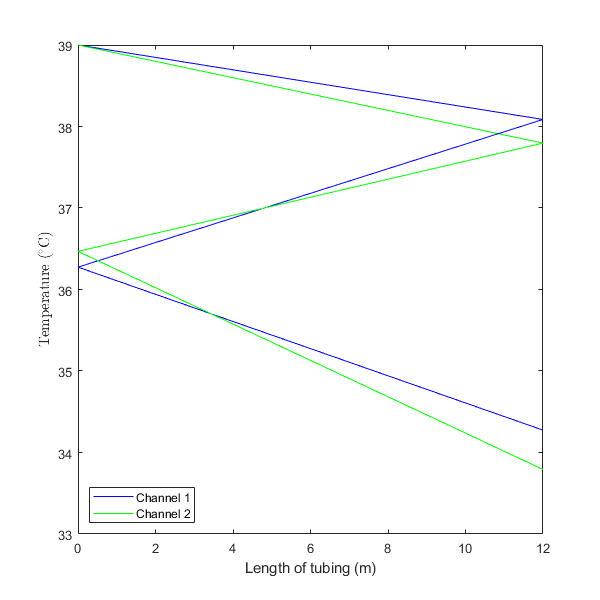

figure;
plot([0 L_tube], [T(1) T(2)] ,'b'); hold on;
plot([0 L_tube], [T(5) T(6)] ,'g'); hold on;
plot([L_tube 0], [T(2) T(3)] ,'b'); hold on;
plot([0 L_tube], [T(3) T(4)] ,'b'); hold on;
plot([L_tube 0], [T(6) T(7)] ,'g'); hold on;
plot([0 L_tube], [T(7) T(8)] ,'g'); hold on;
xlabel('Length of tubing (m)');
ylabel("Temperature ($^\circ \mathrm{C}$)", 'Interpreter',"latex");
legend("Channel 1", "Channel 2",'location','southwest')
set(gcf,'Position',[100 100 600 600]);

The mean temperature in the tube side is calculated as the average of both the tubing channels. 

Tf = (T(4) + T(8))/2 % °C

Tf = 34.0332

It can be seen that the mean temperature is very close to the required outlet temperature for the tube side.

Additionally, the temperature variation of air is also plotted and it is to be noted that the outlet temperature of air is also as expected from previous analysis.

tout = t(1) % °C

tout = 34.7334

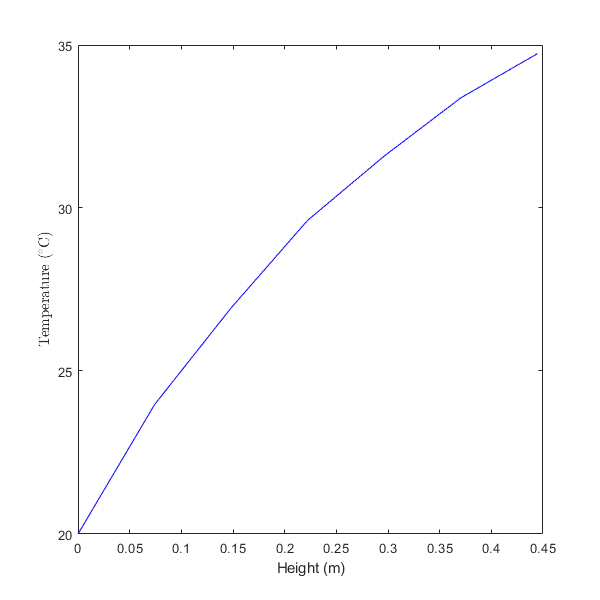


X = H/6*(7 - linspace(1,7,7));
figure;
plot(X,t,'b'); 
xlabel('Height (m)');
ylabel("Temperature ($^\circ \mathrm{C}$)", 'Interpreter',"latex");
set(gcf,'Position',[100 100 600 600]);

Also, the temperature variation along the two flows are compared across the length.

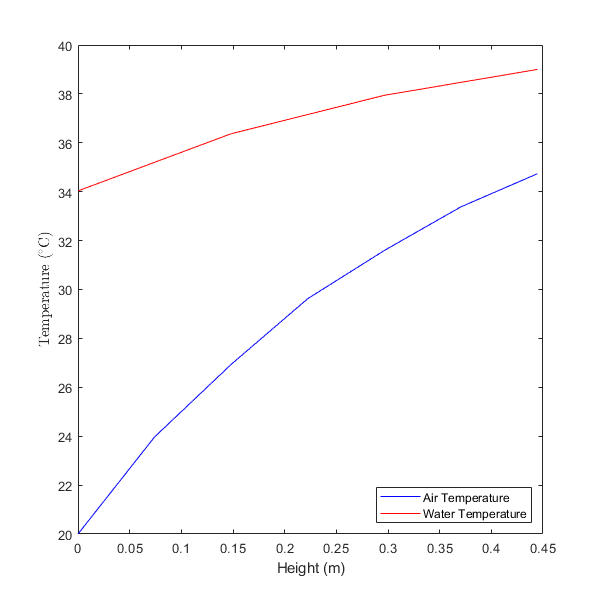

Tw(1) = 0.5*(T(1) + T(5)); Tw(2) = 0.5*(T(2) + T(6));
Tw(3) = 0.5*(T(7) + T(3)); Tw(4) = 0.5*(T(4) + T(8));
X1 = H*(1 - linspace(0,1,4));

plot(X,t,'b',X1,Tw,'r');
xlabel('Height (m)');
ylabel("Temperature ($^\circ \mathrm{C}$)", 'Interpreter',"latex");
legend("Air Temperature", "Water Temperature",'location','southeast');

set(gcf,'Position',[100 100 600 600]);

## 20. Cost Estimation

The constants are referenced from D. Milligan's Heat Exchanger Cost Estimate website which estimates the cost in 2014.

b = A*10.7639; % ft^2
c = 4.41; % Material Factor (for Stainless Steel)
d = 0.62; % Pressure Factor
e = 2963;
f = 0.396;

The cost in USD per heat exchanger is then determined using the below correlation.

cost = e*b^f*c*d % 2014 Model

cost = 2.6403e+05

The total estimated cost is then determined taking into account the number of heat exchangers, the USD to EUR conversion factor and the inflation factor.

cost = cost*N_hex;
cost = cost*0.92;
Inflation_factor = 1.06;
Cost = cost*Inflation_factor % in EUR

Cost = 5.1496e+05